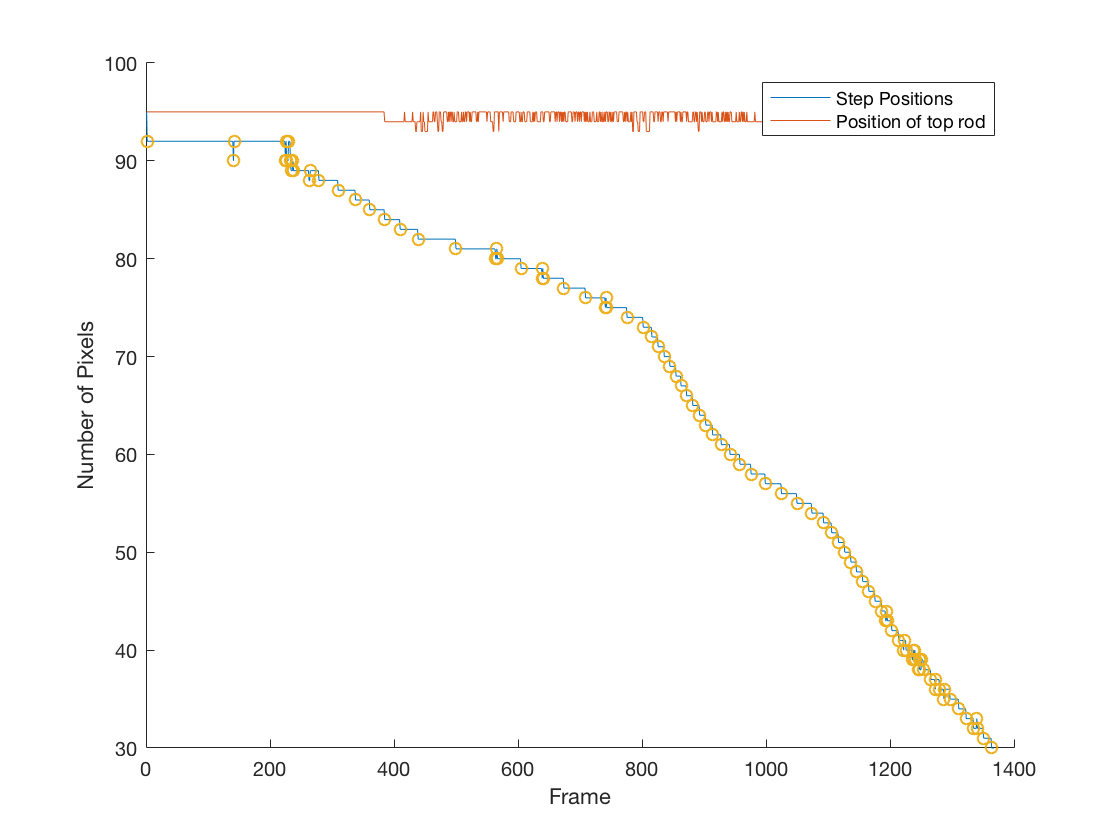

% Video post processing script to analyse high speed footage of cavitation
% between two parallel discs
% Jonathan Lansang, Marc Krueger-Sprengel 10/13/2017

clc;
clear all;
close all;

%% Debugging parameters
debug=false;
boxPlotStart = 150;
boxPlotEnd = 180;

%% Initialization and Parameter input
dRod = 0.015875;
dRodPx = 358;
sizePx = dRod/dRodPx;
frameRate = 160000;
tFrame = 1/frameRate;

step = 0.00; % sensitivity deviation
sigma = 2; % magnitude of Gaussian blur
framesAnalyze = 10;
minLength = 30;
sensitivity = 20;
initialGap = 3;
yTrack = zeros(framesAnalyze,2);


% Tracking parameters


v = 'run5_newLight_gap.mov';
[frames,numFrames] = loadFrames(v); %loadFrames returns int8 cell array of each frame

     
%% Tracking Rod
for i = 1:numFrames
image = frames{round(i)};

%TODO: Add preprocessing helpers (image_gauss etc.)
image_prewittGauss = filterImage(image,sigma);

[xmin,xmax,ymin,ymax] = findEdges(image_prewittGauss,minLength);

%TODO: Add boxplottinghelper
if debug==true
    boundaryBoxHelper(ymin,ymax,image) %CODE HELPER for box plotting
end

yTrack(i,1) = ymin; %position of top rod
yTrack(i,2) = ymax; %position of bottom rod
end
 
%% Data smoothing

[yTrack,bottomRodPos] = throwOutliers(frames,yTrack,initialGap,minLength,sensitivity,sigma);

%% Calculate step positions
steps = findSteps(yTrack);

%% Velocity, pressure and acceleration calculation
[velocity, acceleration] = velAcc(steps, sizePx, tFrame);

relPressure = relPressure(velocity,steps,bottomRodPos,dRod,sizePx);


%% Plotting

plotDisplacement(numFrames,yTrack,steps)